close("all"); clear; clc;

vx = 130/3.6;
p = bikeSimToSharp(bigSportsParameters());
sys = sharpMotorcycleStateSpaceFactory(vx,p);

A = [
    zeros(1,4),1,zeros(1,4);
    zeros(8,1),sys.a
    ];

B = [
    0;
    sys.b
    ];

lsys = linearSys(A,B);

ts = 1/1E03;
tf = 1.5;

x0 = zeros(9,1);
umax = 50;

options.timeStep = ts;
options.zonotopeOrder = 20;
options.taylorTerms = 10;

params.tFinal = tf;
params.R0 = zonotope(interval(x0,x0));
params.U = zonotope(interval(-umax,umax));
R = project(reach(lsys,params,options),[1,4]);

v = cellfun(@vertices,R.timePoint.set.',"uniform",0);
xl = bound(@min,v);
xu = bound(@max,v);

f = @(x)positionRates(vx,x);
p0 = [0;-1.75;0];
pl = p0 + ts.*cumsum(cell2mat(cellfun(f,xl,"uniform",0)),2);
pu = p0 + ts.*cumsum(cell2mat(cellfun(f,xu,"uniform",0)),2);

rd = Road();
rd.addStraight(ceil(pl(1,end)));

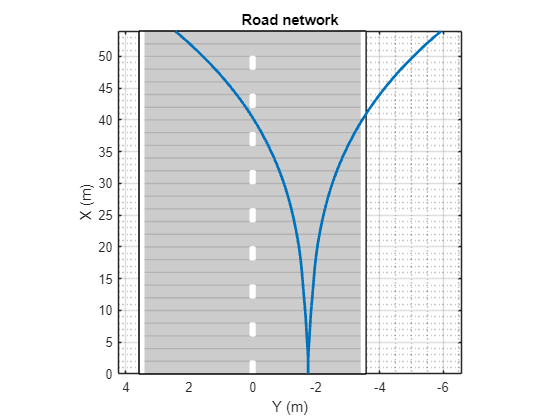

plot(rd);
fig = gcf;
axe = fig.Children;
f = @(p)plot(p(1,:),p(2,:), ...
    "Color",mcolor('b'), ...
    "LineWidth",2);
hold(axe,"on");
f(pl);
f(pu);
hold(axe,"off");
box(axe,"on");
daspect(axe,[5,1,1]);

pathstr = "C:/Users/marti/PhD/Meetings/June24/";
saveas(fig,pathstr + "road","epsc");

function xb = boundHelper(f,x)
    yaw = x(1,:);
    [yaw_k,k] = f(yaw);
    xb = [
        yaw_k;
        x(2,k)
        ];
end

function  xb = bound(f,x)
    xb = cellfun(@(x)boundHelper(f,x),x,"uniform",0);
end

function Xd = positionRates(vx,xb)
    Xd = rotz(rad2deg(xb(1)))*[vx;xb(2);0];
end